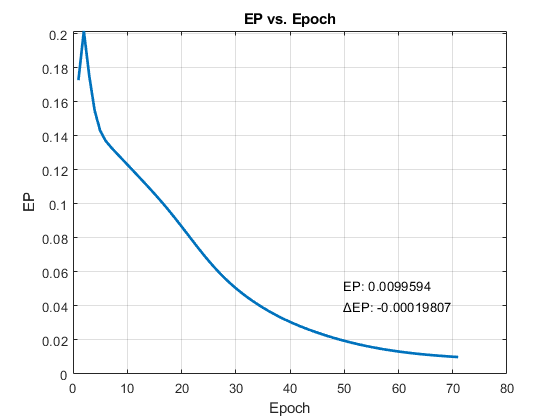

% Membaca dataset
data = readtable('iris.data.csv');
input = table2array(data(:, 1:end-1)); % Asumsikan kolom terakhir adalah label
labels = data{:, end}; % Gunakan kurung kurawal untuk mengakses data dalam tabel

% Konversi label teks menjadi angka
uniqueLabels = unique(labels);
target = zeros(height(data), 1);
for i = 1:length(uniqueLabels)
    target(strcmp(labels, uniqueLabels{i})) = i;
end

% Normalisasi data
input = (input - min(input)) ./ (max(input) - min(input));

% Membagi dataset menjadi training dan testing dengan Stratified Sampling
ratio = 0.7;
uniqueTargets = unique(target);
trainIdx = [];
testIdx = [];

for i = 1:length(uniqueTargets)
    classIdx = find(target == uniqueTargets(i)); % Indeks dari kelas tertentu
    numTrainClass = round(ratio * length(classIdx));
    
    randClassIdx = randperm(length(classIdx));
    
    trainClassIdx = classIdx(randClassIdx(1:numTrainClass));
    testClassIdx = classIdx(randClassIdx(numTrainClass+1:end));
    
    trainIdx = [trainIdx; trainClassIdx];
    testIdx = [testIdx; testClassIdx];
end

inputTrain = input(trainIdx, :);
targetTrain = target(trainIdx);
inputTest = input(testIdx, :);
targetTest = target(testIdx);

% % Membagi dataset menjadi training dan testing
% ratio = 0.7;
% numTrain = round(ratio * size(input, 1));
% randIdx = randperm(size(input, 1));
% trainIdx = randIdx(1:numTrain);
% testIdx = randIdx(numTrain+1:end);
% 
% inputTrain = input(trainIdx, :);
% targetTrain = target(trainIdx);
% inputTest = input(testIdx, :);
% targetTest = target(testIdx);

% Inisialisasi
alpha = 0.4; %kecepatan learning
miu = 0.75; %momentum learning
n = size(inputTrain, 2); % Jumlah fitur
m = 10; % Jumlah neuron di hidden layer
l = length(unique(targetTrain)); % Jumlah kelas
max_epoch = 10000;
EP = inf;

% Inisialisasi bobot dan bias dengan Nguyen-Widrow
beta = 0.7 * m^(1/n);
v = rand(n, m) * 2 - 1;
normV = sqrt(sum(v.^2));
v = beta * v ./ normV;
v0 = (rand(1, m) * 2 - 1) * beta;
w = rand(m, l) * 2 - 1;
w0 = rand(1, l) * 2 - 1;

%inisialiasi momentum perubahan bobot
deltaWPrev = zeros(size(w));
deltaVPrev = zeros(size(v));
deltaW0Prev = zeros(size(w0));
deltaV0Prev = zeros(size(v0));

epoch = 0;
previousEP = 0; %untuk kebutuhan grafik realtime
errorList = []; % Untuk menyimpan error pada setiap epoch
figure; % Membuka jendela figure untuk grafik


while EP > 0.01 && epoch < max_epoch
    EP = 0;
    for p = 1:size(inputTrain, 1)
        xi = inputTrain(p, :);
        tk = zeros(1, l);
        tk(targetTrain(p)) = 1;

        % Feedforward
        z_in = zeros(1, m);
        z = zeros(1, m);
        for j = 1:m
            z_in(j) = xi * v(:, j) + v0(j);
            z(j) = 1 / (1 + exp(-z_in(j)));
        end
        
        y_in = zeros(1, l);
        y = zeros(1, l);
        for k = 1:l
            y_in(k) = z * w(:, k) + w0(k);
            y(k) = 1 / (1 + exp(-y_in(k)));
        end
        
        % Backpropagation
        delta_k = zeros(1, l);
        for k = 1:l
            delta_k(k) = (tk(k) - y(k)) * y(k) * (1 - y(k));
        end
        
        delta_j = zeros(1, m);
        for j = 1:m
            sum_delta_w = 0;
            for k = 1:l
                sum_delta_w = sum_delta_w + delta_k(k) * w(j, k);
            end
            delta_j(j) = sum_delta_w * z(j) * (1 - z(j));
        end

        % Update bobot dan bias dengan momentum
        for k = 1:l
            for j = 1:m
                deltaW = alpha * delta_k(k) * z(j);
                w(j, k) = w(j, k) + deltaW + miu * deltaWPrev(j, k);
                deltaWPrev(j, k) = deltaW;
            end
            deltaW0 = alpha * delta_k(k);
            w0(k) = w0(k) + deltaW0 + miu * deltaW0Prev(k);
            deltaW0Prev(k) = deltaW0;
        end
        
        for j = 1:m
            for i = 1:n
                deltaV = alpha * delta_j(j) * xi(i);
                v(i, j) = v(i, j) + deltaV + miu * deltaVPrev(i, j);
                deltaVPrev(i, j) = deltaV;
            end
            deltaV0 = alpha * delta_j(j);
            v0(j) = v0(j) + deltaV0 + miu * deltaV0Prev(j);
            deltaV0Prev(j) = deltaV0;
        end


        EP = EP + sum((tk - y).^2)/2;

    end
    EP = EP / size(inputTrain, 1);
    epoch = epoch + 1;
    errorList = [errorList, EP]; % Menambahkan error ke list

    % Plotting grafik Error per Epoch (EP)
    plot(errorList, 'LineWidth', 2);
    title('EP vs. Epoch');
    xlabel('Epoch');
    ylabel('EP');
    grid on;
    
   % Menampilkan nilai EP saat ini
    strEP = ['EP: ' num2str(EP)];
    hTextEP = annotation('textbox', [0.6, 0.25, 0.3, 0.1], 'String', strEP, 'EdgeColor', 'none', 'VerticalAlignment', 'top');
    
    % Menampilkan perubahan EP
    deltaEP = EP - previousEP;
    strDeltaEP = ['ΔEP: ' num2str(deltaEP)];
    hTextDeltaEP = annotation('textbox', [0.6, 0.2, 0.3, 0.1], 'String', strDeltaEP, 'EdgeColor', 'none', 'VerticalAlignment', 'top');
    
    drawnow; % Memperbarui grafik secara real-time
    previousEP = EP;
end


disp(['Training selesai setelah ' num2str(epoch) ' epoch dengan error ' num2str(EP)]);

Training selesai setelah 71 epoch dengan error 0.0099594


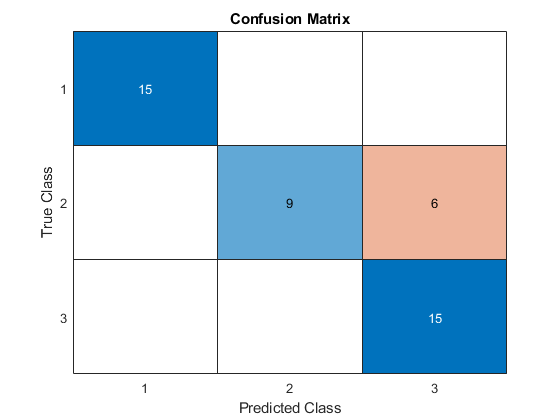


% Evaluasi pada dataset testing
correct = 0;
for p = 1:size(inputTest, 1)
    xi = inputTest(p, :);
    tk = zeros(1, l);
    tk(targetTest(p)) = 1;

    % Feedforward
    z_in = zeros(1, m);
    z = zeros(1, m);
    for j = 1:m
        for i = 1:n
            z_in(j) = z_in(j) + xi(i) * v(i, j);
        end
        z_in(j) = z_in(j) + v0(j);
        z(j) = 1 / (1 + exp(-z_in(j)));
    end
    
    y_in = zeros(1, l);
    y = zeros(1, l);
    for k = 1:l
        for j = 1:m
            y_in(k) = y_in(k) + z(j) * w(j, k);
        end
        y_in(k) = y_in(k) + w0(k);
        y(k) = 1 / (1 + exp(-y_in(k)));
    end

    [~, predicted] = max(y);
    predictedLabels(p) = predicted;
    if predicted == targetTest(p)
        correct = correct + 1;
    end
end
    figure; % Membuka jendela figure baru
    confusionchart(targetTest, predictedLabels);
    title('Confusion Matrix');

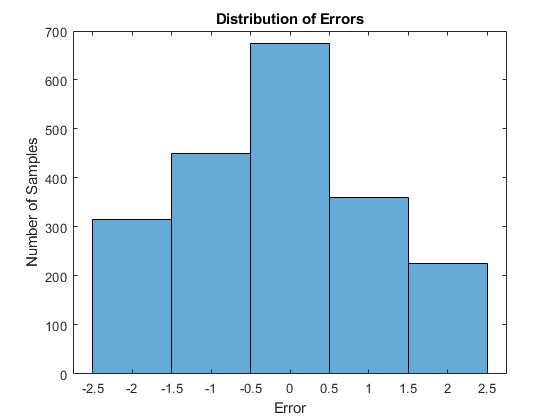

    
    % Visualisasi Kesalahan
    errors = targetTest - predictedLabels;
    figure; % Membuka jendela figure baru
    histogram(errors);
    title('Distribution of Errors');
    xlabel('Error');
    ylabel('Number of Samples');



accuracy = correct / size(inputTest, 1) * 100;
disp(['Akurasi pada dataset testing: ' num2str(accuracy) '%']);

Akurasi pada dataset testing: 86.6667%


% function plot_neural_net(layers, weights)
%     figure;
%     hold on;
%     
%     % Jumlah layer
%     num_layers = length(layers);
%     
%     % Posisi node di setiap layer
%     positions = cell(1, num_layers);
%     
%     % Plot node
%     for i = 1:num_layers
%         layer_size = layers(i);
%         positions{i} = zeros(layer_size, 2);
%         
%         for j = 1:layer_size
%             x = i;
%             y = (1 - layer_size) / 2 + j;
%             positions{i}(j, :) = [x, y];
%             plot(x, y, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
%         end
%     end
%     
%     % Plot koneksi dan bobot
%     for i = 1:num_layers-1
%         for j = 1:layers(i)
%             for k = 1:layers(i+1)
%                 x = [positions{i}(j, 1), positions{i+1}(k, 1)];
%                 y = [positions{i}(j, 2), positions{i+1}(k, 2)];
%                 plot(x, y, 'k-');
%                 
%                 % Menampilkan bobot
%                 mid_x = mean(x);
%                 mid_y = mean(y);
%                 text(mid_x, mid_y, num2str(weights{i}(j, k)), 'BackgroundColor', 'w');
%             end
%         end
%     end
%     
%     axis off;
%     hold off;
% end
% 